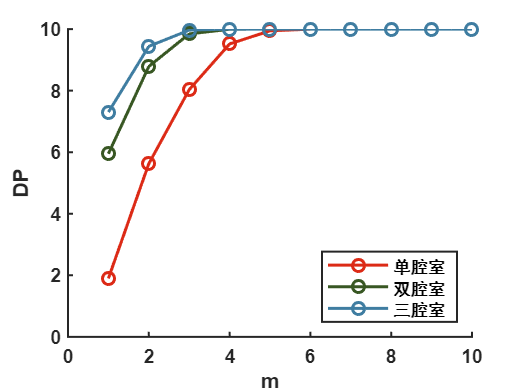

%考察单腔室与双腔室笼对互锁聚合度的影响
clear all 
syms p m l y r q k a1 a2 a3 a4 t;

a1=[];
a2=[];
a3=[];
a4=[];
y1=[];
y2=[];
y3=[];

hold on
axis([0 10 0 10]);

p=0.9; % p为互锁转化率
for m=1:1:10 % m为一个笼腔内最多可容纳的盖子数
    for k=1:1:m-1
        t=(k+1)/(3*k-1);
        a1=[a1,t];
    end
    q=1-((m+1)/(3*m-1)); %1-q为前体结构进一步形成闭锁的概率
    r=1-(prod(a1)); %1-r为形成闭锁结构前驱体的概率
    y=(1-(p^(m+1))*(1-q)*(1-r))/(1-p);
    y1=[y1,y];
end
x1=[1:1:10];
plot(x1,y1,'-o','LineWidth',1.5, ...
    'color',[221, 42, 22]/256,'DisplayName','单腔室')

p=0.9; 
for m=1:1:10 
    for k=1:1:m-1
        t=(k+1)/(5*k-1);
        a2=[a2,t];
    end
    q=1-((m+1)/(5*m-1)); 
    r=1-(prod(a2)); 
    y=(1-(p^(m+1))*(1-q)*(1-r))/(1-p);
    y2=[y2,y];
end
x2=[1:1:10];
plot(x2,y2,'-o','LineWidth',1.5, ...
    'color',[56, 87, 35]/256,'DisplayName','双腔室')

p=0.9; 
for m=1:1:10 
    for k=1:1:m-1
        t=(k+1)/(7*k-1);
        a3=[a3,t];
    end
    q=1-((m+1)/(7*m-1)); 
    r=1-(prod(a3)); 
    y=(1-(p^(m+1))*(1-q)*(1-r))/(1-p);
    y3=[y3,y];
end
x3=[1:1:10];
plot(x3,y3,'-o','LineWidth',1.5, ...
    'color',[63, 125, 162]/256,'DisplayName','三腔室')

hold off

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('m','FontName','arial','FontWeight','bold'); 
ylabel('DP','FontName','arial','FontWeight','bold');
legend('Location','southeast','FontName','黑体');